# Visual SLAM with an RGB-D Camera

Visual simultaneous localization and mapping (vSLAM), refers to the process of calculating the position and orientation of a camera with respect to its surroundings, while simultaneously mapping the environment. 

You can perform vSLAM using a monocular camera. However, the depth cannot be accurately calculated, and the estimated trajectory is unknown and drifts over time. To produce an initial map, which cannot be triangulated from the first frame, you must use multiple views of a monocular camera. A better, more reliable solution is to use an RGB-D camera, which is composed of one RGB color image and one depth image.

This example shows how to process RGB-D image data to build a map of an indoor environment and estimate the trajectory of the camera. The example uses a version of the ORB-SLAM2 [1] algorithm, which is feature-based and supports RGB-D cameras.

## **Overview of Processing Pipeline**

The pipeline for RGB-D vSLAM is very similar to the monocular vSLAM pipeline in the [Monocular Visual Simultaneous Localization and Mapping](docid:vision_ug#mw_3eb27c60-ed2c-4eb7-8c66-4f53a04fbc22) example. The major difference is that in the **Map Initialization** stage, the 3-D map points are created from a pair of images consisting of one color image and one depth image instead of two frames of color images.

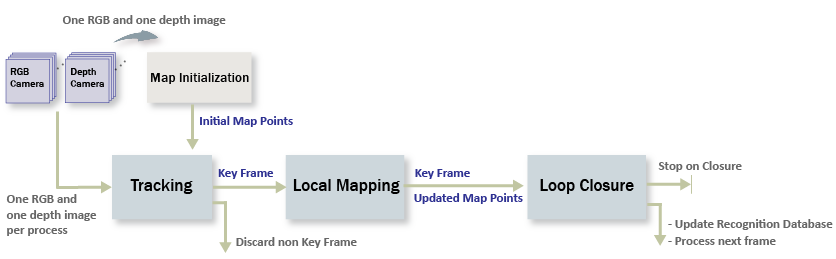

- **Map Initialization**: The initial 3-D world points can be constructed by extracting ORB feature points from the color image and then computing their 3-D world locations from the depth image. The color image is stored as the first key frame. 

- **Tracking**: Once a map is initialized, the pose of the camera is estimated for each new RGB-D image by matching features in the color image to features in the last key frame.

- **Local Mapping**: If the current color image is identified as a key frame, new 3-D map points are computed from the depth image.  At this stage, bundle adjustment is used to minimize reprojection errors by adjusting the camera pose and 3-D points.  

- **Loop Closure**: Loops are detected for each key frame by comparing it against all previous key frames using the bag-of-features approach. Once a loop closure is detected, the pose graph is optimized to refine the camera poses of all the key frames.

## **Download and Explore the Input Image Sequence**

The data used in this example is from the [TUM RGB-D benchmark](https://cvg.cit.tum.de/data/datasets/rgbd-dataset) [2]. You can download the data to a temporary folder using a web browser or by running the following code:

baseDownloadURL = "https://cvg.cit.tum.de/rgbd/dataset/freiburg3/rgbd_dataset_freiburg3_long_office_household.tgz"; 
dataFolder      = fullfile(tempdir, 'tum_rgbd_dataset', filesep); 
options         = weboptions('Timeout', Inf);
tgzFileName     = [dataFolder, 'fr3_office.tgz'];
folderExists    = exist(dataFolder, 'dir');

% Create a folder in a temporary directory to save the downloaded file
if ~folderExists  
    mkdir(dataFolder); 
    disp('Downloading fr3_office.tgz (1.38 GB). This download can take a few minutes.') 
    websave(tgzFileName, baseDownloadURL, options); 
    
    % Extract contents of the downloaded file
    disp('Extracting fr3_office.tgz (1.38 GB) ...') 
    untar(tgzFileName, dataFolder); 
end

Extracting fr3_office.tgz (1.38 GB) ...


imageFolder = [dataFolder, 'rgbd_dataset_freiburg3_long_office_household/'];


Create two [`imageDatastore`](docid:matlab_ref#butueui-1) objects to store the color and depth images, respectively.

imgFolderColor = [imageFolder,'rgb/'];
imgFolderDepth = [imageFolder,'depth/'];
imdsColor      = imageDatastore(imgFolderColor);
imdsDepth      = imageDatastore(imgFolderDepth);

Note that the color and depth images are generated in an un-synchronized way in the dataset. Therefore, we need to associate color images to depth images based on the time stamp.

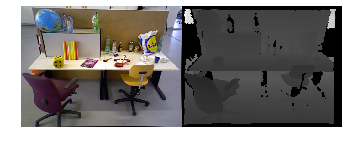

% Load time stamp data of color images
timeColor = helperImportTimestampFile([imageFolder, 'rgb.txt']);

% Load time stamp data of depth images
timeDepth = helperImportTimestampFile([imageFolder, 'depth.txt']);

% Align the time stamp
indexPairs = helperAlignTimestamp(timeColor, timeDepth);

% Select the synchronized image data
imdsColor     = subset(imdsColor, indexPairs(:, 1));
imdsDepth     = subset(imdsDepth, indexPairs(:, 2));

% Inspect the first RGB-D image
currFrameIdx  = 1;
currIcolor    = readimage(imdsColor, currFrameIdx);
currIdepth    = readimage(imdsDepth, currFrameIdx);
imshowpair(currIcolor, currIdepth, "montage");

## **Map Initialization**

The pipeline starts by initializing the map that holds 3-D world points. This step is crucial and has a significant impact on the accuracy of the final SLAM result. Initial ORB feature points are extracted from the first color image using `helperDetectAndExtractFeatures`. Their corresponding 3-D world locations can be computed from the pixel coordinates of the feature points and the depth value using `helperReconstructFromRGBD`.

% Set random seed for reproducibility
rng(0);

% Create a cameraIntrinsics object to store the camera intrinsic parameters.
% The intrinsics for the dataset can be found at the following page:
% https://vision.in.tum.de/data/datasets/rgbd-dataset/file_formats
focalLength    = [535.4, 539.2];    % in units of pixels
principalPoint = [320.1, 247.6];    % in units of pixels
imageSize      = size(currIcolor,[1,2]); % in pixels [mrows, ncols]
depthFactor    = 5e3;
intrinsics     = cameraIntrinsics(focalLength,principalPoint,imageSize);

% Detect and extract ORB features from the color image
scaleFactor = 1.2;
numLevels   = 8;
[currFeatures, currPoints] = helperDetectAndExtractFeatures(currIcolor, scaleFactor, numLevels); 

initialPose = rigidtform3d();
[xyzPoints, validIndex] = helperReconstructFromRGBD(currPoints, currIdepth, intrinsics, initialPose, depthFactor);

## **Initialize Place Recognition Database**

Loop detection is performed using the bags-of-words approach. A visual vocabulary represented as a [`bagOfFeatures`](docid:vision_ref#bufbdd6) object is created offline with the ORB descriptors extracted from a large set of images in the dataset by calling:

`bag = bagOfFeatures(imds,CustomExtractor=@helperORBFeatureExtractorFunction, TreeProperties=[5, 10], StrongestFeatures=1);`

where `imds` is an [`imageDatastore`](docid:matlab_ref#butueui-1) object storing the training images and [`helperORBFeatureExtractorFunction`](matlab:openExample('vision/MonocularVisualSimultaneousLocalizationAndMappingExample','supportingFile','helperORBFeatureExtractorFunction.m')) is the ORB feature extractor function. See [Image Retrieval with Bag of Visual Words](docid:vision_ug#bun8icv-1) for more information.

The loop closure process incrementally builds a database, represented as an [`invertedImageIndex`](docid:vision_ref#bumxjai-1) object, that stores the visual word-to-image mapping based on the bag of ORB features.

% Load the bag of features data created offline
bofData         = load("bagOfFeaturesDataSLAM.mat");

% Initialize the place recognition database
loopDatabase    = invertedImageIndex(bofData.bof, SaveFeatureLocations=false);

% Add features of the first key frame to the database
currKeyFrameId = 1;
addImageFeatures(loopDatabase, currFeatures, currKeyFrameId);

## Data Management and Visualization

After the map is initialized using the first pair of color and depth image, you can use [`imageviewset`](docid:vision_ref#mw_6e9e9e26-1c92-4289-a7d9-bccafaf79b78) and [`worldpointset`](docid:vision_ref#mw_3d5c7b4a-5b50-436d-a8b0-f20fc3d7a466) to store the first key frames and the corresponding map points:

% Create an empty imageviewset object to store key frames
vSetKeyFrames = imageviewset;

% Create an empty worldpointset object to store 3-D map points
mapPointSet   = worldpointset;

% Add the first key frame
vSetKeyFrames = addView(vSetKeyFrames, currKeyFrameId, initialPose, Points=currPoints,...
    Features=currFeatures.Features);

% Add 3-D map points
[mapPointSet, rgbdMapPointsIdx] = addWorldPoints(mapPointSet, xyzPoints);

% Add observations of the map points
mapPointSet = addCorrespondences(mapPointSet, currKeyFrameId, rgbdMapPointsIdx, validIndex);

% Update view direction and depth
mapPointSet = updateLimitsAndDirection(mapPointSet, rgbdMapPointsIdx, vSetKeyFrames.Views);

% Update representative view
mapPointSet = updateRepresentativeView(mapPointSet, rgbdMapPointsIdx, vSetKeyFrames.Views);

% Visualize matched features in the first key frame
featurePlot = helperVisualizeMatchedFeaturesRGBD(currIcolor, currIdepth, currPoints(validIndex));

% Visualize initial map points and camera trajectory
xLim = [-4 4];
yLim = [-3 1];
zLim = [-1 6];
mapPlot  = helperVisualizeMotionAndStructure(vSetKeyFrames, mapPointSet, xLim, yLim, zLim);

% Show legend
showLegend(mapPlot);

## Tracking

The tracking process is performed using every RGB-D image and determines when to insert a new key frame. 

% ViewId of the last key frame
lastKeyFrameId    = currKeyFrameId;

% Index of the last key frame in the input image sequence
lastKeyFrameIdx   = currFrameIdx; 

% Indices of all the key frames in the input image sequence
addedFramesIdx    = lastKeyFrameIdx;

currFrameIdx      = 2;
isLoopClosed      = false;

Each frame is processed as follows:

- ORB features are extracted for each new color image and then matched (using [`matchFeatures`](docid:vision_ref#bsvbhh1-1)), with features in the last key frame that have known corresponding 3-D map points.

- Estimate the camera pose using *Perspective-n-Point *algorithm*, *which estimates the pose of a calibrated camera given a set of 3-D points and their corresponding 2-D projections using [`estworldpose`](docid:vision_ref#mw_9685837b-561a-4e27-a7c5-0e1ac2d32fd8).

- Given the camera pose, project the map points observed by the last key frame into the current frame and search for feature correspondences using  [`matchFeaturesInRadius`](docid:vision_ref#mw_098d719d-da7d-45dd-81aa-ddab5fdfc9a4).

- With 3-D to 2-D correspondences in the current frame, refine the camera pose by performing a motion-only bundle adjustment using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf).

- Project the local map points into the current frame to search for more feature correspondences using [`matchFeaturesInRadius`](docid:vision_ref#mw_098d719d-da7d-45dd-81aa-ddab5fdfc9a4) and refine the camera pose again using [`bundleAdjustmentMotion`](docid:vision_ref#mw_11887bed-7a1c-44d8-929a-e5401685ddcf).

- The last step of tracking is to decide if the current frame should be a new key frame. A frame is a key frame if both of the following conditions are satisfied:

- At least 20 frames have passed since the last key frame or the current frame tracks fewer than 100 map points or 25% of points tracked by the reference key frame.

- The map points tracked by the current frame are fewer than 90% of points tracked by the reference key frame.

            If the current frame is to become a key frame, continue to the **Local Mapping **process. Otherwise, start **Tracking** for the next frame.

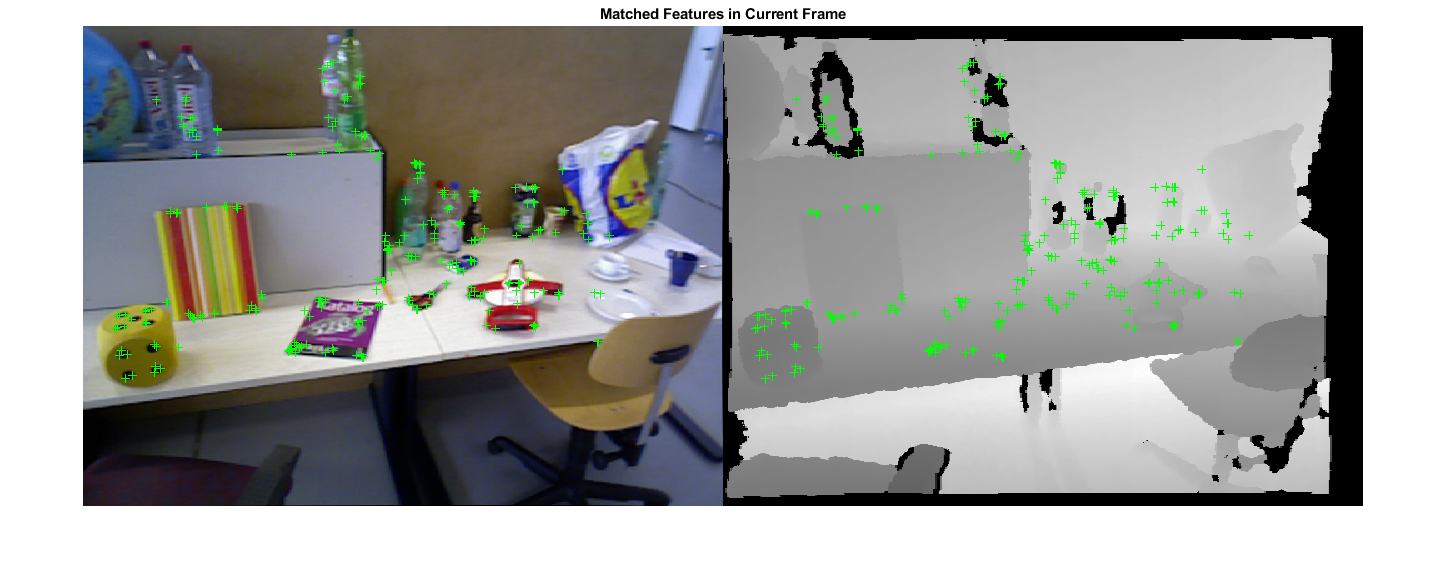

Loop edge added between keyframe: 4 and 87
Loop edge added between keyframe: 3 and 87


% Main loop
isLastFrameKeyFrame = true;
while ~isLoopClosed && currFrameIdx < numel(imdsColor.Files)

    currIcolor = readimage(imdsColor, currFrameIdx);
    currIdepth = readimage(imdsDepth, currFrameIdx);

    [currFeatures, currPoints]    = helperDetectAndExtractFeatures(currIcolor, scaleFactor, numLevels);

    % Track the last key frame
    % trackedMapPointsIdx:  Indices of the map points observed in the current left frame 
    % trackedFeatureIdx:    Indices of the corresponding feature points in the current left frame
    [currPose, trackedMapPointsIdx, trackedFeatureIdx] = helperTrackLastKeyFrame(mapPointSet, ...
        vSetKeyFrames.Views, currFeatures, currPoints, lastKeyFrameId, intrinsics, scaleFactor);
    
    if isempty(currPose) || numel(trackedMapPointsIdx) < 30
        currFrameIdx = currFrameIdx + 1;
        continue
    end
    
    % Track the local map and check if the current frame is a key frame.
    % A frame is a key frame if both of the following conditions are satisfied:
    %
    % 1. At least 20 frames have passed since the last key frame or the 
    %    current frame tracks fewer than 100 map points. 
    % 2. The map points tracked by the current frame are fewer than 90% of 
    %    points tracked by the reference key frame.
    %
    % localKeyFrameIds:   ViewId of the connected key frames of the current frame
    numSkipFrames     = 20;
    numPointsKeyFrame = 100;
    [localKeyFrameIds, currPose, trackedMapPointsIdx, trackedFeatureIdx, isKeyFrame] = ...
        helperTrackLocalMap(mapPointSet, vSetKeyFrames, trackedMapPointsIdx, ...
        trackedFeatureIdx, currPose, currFeatures, currPoints, intrinsics, scaleFactor, numLevels, ...
        isLastFrameKeyFrame, lastKeyFrameIdx, currFrameIdx, numSkipFrames, numPointsKeyFrame);

    % Visualize matched features
    updatePlot(featurePlot, currIcolor, currIdepth, currPoints(trackedFeatureIdx));
    
    if ~isKeyFrame
        currFrameIdx = currFrameIdx + 1;
        isLastFrameKeyFrame = false;
        continue
    else
        % Match feature points between the stereo images and get the 3-D world positions
        [xyzPoints, validIndex] = helperReconstructFromRGBD(currPoints, currIdepth, ...
            intrinsics, currPose, depthFactor);

        [untrackedFeatureIdx, ia] = setdiff(validIndex, trackedFeatureIdx);
        xyzPoints = xyzPoints(ia, :);
        isLastFrameKeyFrame = true;
    end

    % Update current key frame ID
    currKeyFrameId  = currKeyFrameId + 1;

## Local Mapping

Local mapping is performed for every key frame. When a new key frame is determined, add it to the key frames and update the attributes of the map points observed by the new key frame. To ensure that `mapPointSet` contains as few outliers as possible, a valid map point must be observed in at least 3 key frames. 

New map points are created by triangulating ORB feature points in the current key frame and its connected key frames. For each unmatched feature point in the current key frame, search for a match with other unmatched points in the connected key frames using [`matchFeatures`](docid:vision_ref#bsvbhh1-1). The local bundle adjustment refines the pose of the current key frame, the poses of connected key frames, and all the map points observed in these key frames.

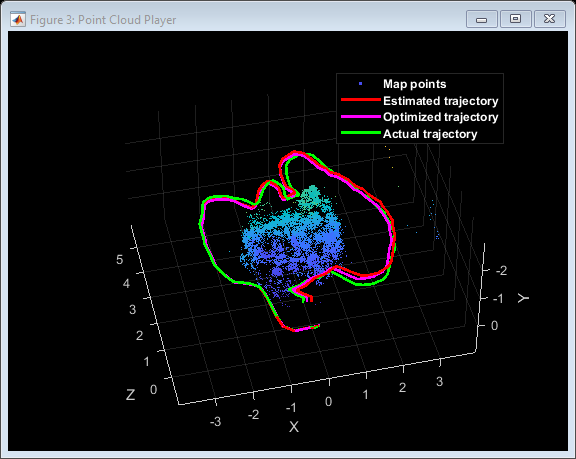


    % Add the new key frame    
    [mapPointSet, vSetKeyFrames] = helperAddNewKeyFrame(mapPointSet, vSetKeyFrames, ...
        currPose, currFeatures, currPoints, trackedMapPointsIdx, trackedFeatureIdx, localKeyFrameIds);
        
    % Remove outlier map points that are observed in fewer than 3 key frames
    if currKeyFrameId == 2
        triangulatedMapPointsIdx = [];
    end
    
    [mapPointSet, trackedMapPointsIdx] = ...
        helperCullRecentMapPoints(mapPointSet, trackedMapPointsIdx, triangulatedMapPointsIdx, ...
        rgbdMapPointsIdx);
    
    % Add new map points computed from disparity 
    [mapPointSet, rgbdMapPointsIdx] = addWorldPoints(mapPointSet, xyzPoints);
    mapPointSet = addCorrespondences(mapPointSet, currKeyFrameId, rgbdMapPointsIdx, ...
        untrackedFeatureIdx);
    
    % Create new map points by triangulation
    minNumMatches = 10;
    minParallax   = 0.35;
    [mapPointSet, vSetKeyFrames, triangulatedMapPointsIdx, rgbdMapPointsIdx] = helperCreateNewMapPointsStereo( ...
        mapPointSet, vSetKeyFrames, currKeyFrameId, intrinsics, scaleFactor, minNumMatches, minParallax, ...
        untrackedFeatureIdx, rgbdMapPointsIdx);

    % Update view direction and depth

    mapPointSet = updateLimitsAndDirection(mapPointSet, [triangulatedMapPointsIdx; rgbdMapPointsIdx], ...
        vSetKeyFrames.Views);

Absolute RMSE for key frame trajectory (m): 0.15358



    % Update representative view
    mapPointSet = updateRepresentativeView(mapPointSet, [triangulatedMapPointsIdx; rgbdMapPointsIdx], ...
        vSetKeyFrames.Views);

    % Local bundle adjustment
    [mapPointSet, vSetKeyFrames, triangulatedMapPointsIdx, rgbdMapPointsIdx] = ...
        helperLocalBundleAdjustmentStereo(mapPointSet, vSetKeyFrames, ...
        currKeyFrameId, intrinsics, triangulatedMapPointsIdx, rgbdMapPointsIdx);

    % Visualize 3-D world points and camera trajectory
    updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

## Loop Closure

The loop closure detection step takes the current key frame processed by the local mapping process and tries to detect and close the loop. Loop candidates are identified by querying images in the database that are visually similar to the current key frame using [`evaluateImageRetrieval`](docid:vision_ref#bumxi3p-1). A candidate key frame is valid if it is not connected to the last key frame and three of its neighbor key frames are loop candidates.

When a valid loop candidate is found, use [`estgeotform3d`](docid:vision_ref#mw_2e99afb0-9afd-4353-8f9e-9de2e40ee066) to compute the relative pose between the loop candidate frame and the current key frame. The relative pose represents a 3-D rigid transformation stored in a [`rigidtform3d`](docid:images_ref#mw_ac5763d9-ceb0-44c0-85af-41d437cc74b4) object. Then add the loop connection with the relative pose and update `mapPointSet` and `vSetKeyFrames`.

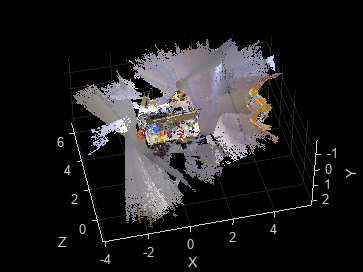

    % Check loop closure after some key frames have been created    
    if currKeyFrameId > 20
        
        % Minimum number of feature matches of loop edges
        loopEdgeNumMatches = 120;
        
        % Detect possible loop closure key frame candidates
        [isDetected, validLoopCandidates] = helperCheckLoopClosure(vSetKeyFrames, currKeyFrameId, ...

            loopDatabase, currIcolor, loopEdgeNumMatches);
        
        if isDetected 
            % Add loop closure connections
            maxDistance = 0.1;
            [isLoopClosed, mapPointSet, vSetKeyFrames] = helperAddLoopConnectionsStereo(...
                mapPointSet, vSetKeyFrames, validLoopCandidates, currKeyFrameId, ...
                currFeatures, currPoints, loopEdgeNumMatches, maxDistance);
        end
    end
    
    % If no loop closure is detected, add current features into the database
    if ~isLoopClosed
        addImageFeatures(loopDatabase,  currFeatures, currKeyFrameId);
    end
    
    % Update IDs and indices
    lastKeyFrameId  = currKeyFrameId;
    lastKeyFrameIdx = currFrameIdx;
    addedFramesIdx  = [addedFramesIdx; currFrameIdx]; %#ok<AGROW>
    currFrameIdx    = currFrameIdx + 1;
end % End of main loop

Finally, apply pose graph optimization over the essential graph in `vSetKeyFrames `to correct the drift. The essential graph is created internally by removing connections with fewer than `minNumMatches `matches in the covisibility graph. After pose graph optimization, update the 3-D locations of the map points using the optimized poses.

% Optimize the poses
minNumMatches      = 50;
vSetKeyFramesOptim = optimizePoses(vSetKeyFrames, minNumMatches, Tolerance=1e-16);

% Update map points after optimizing the poses
mapPointSet = helperUpdateGlobalMap(mapPointSet, vSetKeyFrames, vSetKeyFramesOptim);

updatePlot(mapPlot, vSetKeyFrames, mapPointSet);

% Plot the optimized camera trajectory
optimizedPoses  = poses(vSetKeyFramesOptim);
plotOptimizedTrajectory(mapPlot, optimizedPoses)

% Update legend
showLegend(mapPlot);

## Compare with the Ground Truth

You can compare the optimized camera trajectory with the ground truth to evaluate the accuracy. The downloaded data contains a `groundtruth.txt` file that stores the ground truth of camera pose of each frame. The data has been saved in the form of a MAT-file. You can also calculate the root-mean-square-error (RMSE) of trajectory estimates.

% Load ground truth 
gTruthData = load("orbslamGroundTruth.mat");
gTruth     = gTruthData.gTruth;

% Plot the actual camera trajectory 
plotActualTrajectory(mapPlot, gTruth(indexPairs(addedFramesIdx, 1)), optimizedPoses);

% Show legend
showLegend(mapPlot);
% Evaluate tracking accuracy
helperEstimateTrajectoryError(gTruth(indexPairs(addedFramesIdx, 1)), optimizedPoses);

## Dense Reconstruction from Depth Image

Given the refined camera poses, you can reproject all the valid image points in the associated depth images back to the 3-D space to perform dense reconstruction. 

% Create an array of pointCloud objects to store the world points constructed
% from the key frames
ptClouds =  repmat(pointCloud(zeros(1, 3)), numel(addedFramesIdx), 1);

% Ignore image points at the boundary 
offset = 40;
[X, Y] = meshgrid(offset:2:imageSize(2)-offset, offset:2:imageSize(1)-offset);

for i = 1: numel(addedFramesIdx)
    Icolor = readimage(imdsColor, addedFramesIdx(i));
    Idepth = readimage(imdsDepth, addedFramesIdx(i));

    [xyzPoints, validIndex] = helperReconstructFromRGBD([X(:), Y(:)], ...
        Idepth, intrinsics, optimizedPoses.AbsolutePose(i), depthFactor);

    colors = zeros(numel(X), 1, 'like', Icolor);
    for j = 1:numel(X)
        colors(j, 1:3) = Icolor(Y(j), X(j), :);
    end
    ptClouds(i) = pointCloud(xyzPoints, Color=colors(validIndex, :));
end

% Concatenate the point clouds
pointCloudsAll = pccat(ptClouds);

figure
pcshow(pointCloudsAll,VerticalAxis="y", VerticalAxisDir="down");
xlabel('X')
ylabel('Y')
zlabel('Z')

## Supporting Functions

Short helper functions are listed below. Larger function are included in separate files.

`helperImportTimestampFile` Import time stamp file

function timestamp = helperImportTimestampFile(filename)

% Input handling
dataLines = [4, Inf];

%% Set up the Import Options and import the data
opts = delimitedTextImportOptions("NumVariables", 2);

% Specify range and delimiter
opts.DataLines = dataLines;
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["VarName1", "Var2"];
opts.SelectedVariableNames = "VarName1";
opts.VariableTypes = ["double", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Specify variable properties
opts = setvaropts(opts, "Var2", "WhitespaceRule", "preserve");
opts = setvaropts(opts, "Var2", "EmptyFieldRule", "auto");

% Import the data
data = readtable(filename, opts);

% Convert to output type
timestamp = table2array(data);
end

`helperAlignTimestamp` align time stamp of color and depth images.

function indexPairs = helperAlignTimestamp(timeColor, timeDepth)
idxDepth = 1;
indexPairs = zeros(numel(timeColor), 2);
for i = 1:numel(timeColor)
    for j = idxDepth : numel(timeDepth)
        if abs(timeColor(i) - timeDepth(j)) < 1e-4
            idxDepth = j;
            indexPairs(i, :) = [i, j];
            break
        elseif timeDepth(j) - timeColor(i) > 1e-3
            break
        end
    end
end
indexPairs = indexPairs(indexPairs(:,1)>0, :);
end

`helperDetectAndExtractFeatures` detect and extract and ORB features from the image.

function [features, validPoints] = helperDetectAndExtractFeatures(Irgb, scaleFactor, numLevels)
 
numPoints = 1000;

% Detect ORB features
Igray  = rgb2gray(Irgb);

points = detectORBFeatures(Igray, ScaleFactor=scaleFactor, NumLevels=numLevels);

% Select a subset of features, uniformly distributed throughout the image
points = selectUniform(points, numPoints, size(Igray, 1:2));

% Extract features
[features, validPoints] = extractFeatures(Igray, points);
end

`helperReconstructFromRGBD `reconstruct scene from color and depth image.

function [xyzPoints, validIndex] = helperReconstructFromRGBD(points, ...
    depthMap, intrinsics, currPose, depthFactor)

ptcloud = pcfromdepth(depthMap,depthFactor,intrinsics,ImagePoints=points, DepthRange=[0.1, 5]);

isPointValid = ~isnan(ptcloud.Location(:, 1));
xyzPoints    = ptcloud.Location(isPointValid, :);
xyzPoints    = transformPointsForward(currPose, xyzPoints);
validIndex   = find(isPointValid);
end

`helperCullRecentMapPoints` cull recently added map points.

function [mapPointSet, mapPointsIdx] = ...
    helperCullRecentMapPoints(mapPointSet, mapPointsIdx, newPointIdx, rgbdMapPointsIndices)
outlierIdx = setdiff([newPointIdx; rgbdMapPointsIndices], mapPointsIdx);
if ~isempty(outlierIdx)
    mapPointSet   = removeWorldPoints(mapPointSet, outlierIdx);
    mapPointsIdx  = mapPointsIdx - arrayfun(@(x) nnz(x>outlierIdx), mapPointsIdx);
end
end

`helperEstimateTrajectoryError` calculate the tracking error.

function rmse = helperEstimateTrajectoryError(gTruth, cameraPoses)
locations       = vertcat(cameraPoses.AbsolutePose.Translation);
gLocations      = vertcat(gTruth.Translation);
scale           = median(vecnorm(gLocations, 2, 2))/ median(vecnorm(locations, 2, 2));
scaledLocations = locations * scale;

rmse = sqrt(mean( sum((scaledLocations - gLocations).^2, 2) ));
disp(['Absolute RMSE for key frame trajectory (m): ', num2str(rmse)]);
end

`helperUpdateGlobalMap` update 3-D locations of map points after pose graph optimization

function mapPointSet = helperUpdateGlobalMap(mapPointSet, vSetKeyFrames, vSetKeyFramesOptim)

posesOld     = vSetKeyFrames.Views.AbsolutePose;
posesNew     = vSetKeyFramesOptim.Views.AbsolutePose;
positionsOld = mapPointSet.WorldPoints;
positionsNew = positionsOld;
indices = 1:mapPointSet.Count;

% Update world location of each map point based on the new absolute pose of 
% the corresponding major view
for i = 1: mapPointSet.Count
    majorViewIds = mapPointSet.RepresentativeViewId(i);
    tform = rigidtform3d(posesNew(majorViewIds).A/posesOld(majorViewIds).A);
    positionsNew(i, :) = transformPointsForward(tform, positionsOld(i, :));
end
mapPointSet = updateWorldPoints(mapPointSet, indices, positionsNew);
end

## References

[1] Mur-Artal, Raul, and Juan D. Tardos. “ORB-SLAM2: An Open-Source SLAM System for Monocular, Stereo, and RGB-D Cameras.” *IEEE Transactions on Robotics* 33, no. 5 (October 2017): 1255–62.

[2] Sturm, Jürgen, Nikolas Engelhard, Felix Endres, Wolfram Burgard, and Daniel Cremers. “A Benchmark for the Evaluation of RGB-D SLAM Systems.” In *2012 IEEE/RSJ International Conference on Intelligent Robots and Systems*, 573–80, 2012.

*Copyright 2021 The MathWorks, Inc.*